# IAVSD23 - Optimizing rail maintenance

## Input data (lookup table) and interpolation

% set parameters
tonnage = "H_32t";

tonnage = "H_32t"

interpolation_method = 'spline';

interpolation_method = 'spline'


% read lookup tables
[H_table_MB5,H_table_MB6] = read_input_data(tonnage);

% plot table
% plot_figure('H_table5_heatmap', H_table_MB5);
% plot_figure('H_table6_heatmap', H_table_MB6);

% interpolations of H_table
H_table_interpol = interpolation(H_table_MB5,interpolation_method);
H_table_interpol_MB6 = interpolation(H_table_MB6,interpolation_method);
% H_table_interpol_makima = interpolation(H_table_MB5,'makima');
% H_table_interpol_spline = interpolation(H_table_MB5,'spline');
% H_table_interpol_cubic = interpolation(H_table_MB5,'cubic');

% visualize the interpolated H_tables
% plot_figure(strcat(interpolation_method,' interpolation'), H_table_interpol)
% plot_figure(strcat(interpolation_method,' interpolation'), H_table_interpol_MB6)

## LCC Simulation for different maintenance strategies

% average yearly gauge widening (in mm/year)
avg_yearly_gauge_widening = 0:0.1:2;

% find the optimals
opt_grinding = zeros(size(avg_yearly_gauge_widening));
opt_tamping = zeros(size(avg_yearly_gauge_widening));
opt_LCC = zeros(size(avg_yearly_gauge_widening));
opt_grinding_MB6 = zeros(size(avg_yearly_gauge_widening));
opt_tamping_MB6 = zeros(size(avg_yearly_gauge_widening));
opt_LCC_MB6 = zeros(size(avg_yearly_gauge_widening));
for i=1:size(avg_yearly_gauge_widening,2)
    [opt_grinding(i),opt_tamping(i),opt_LCC(i)] = get_optimal(H_table_interpol, interpolation_method, "MB5", avg_yearly_gauge_widening(i));
    [opt_grinding_MB6(i),opt_tamping_MB6(i),opt_LCC_MB6(i)] = get_optimal(H_table_interpol_MB6, interpolation_method, "MB6", avg_yearly_gauge_widening(i));
end

## Plot simulation results

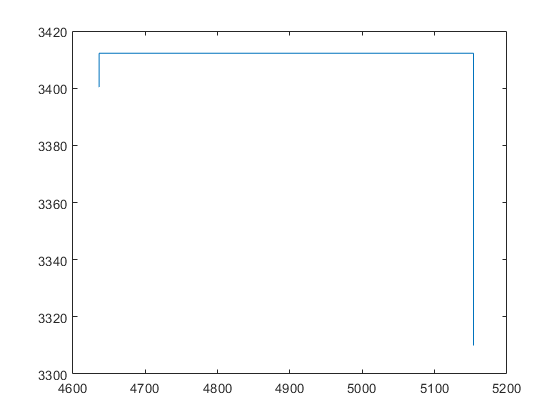

% plot results
plot(opt_LCC, opt_LCC_MB6)